# How Should Apples be Prepared for a Fruit Salad? 

By the end of this module, you should be able to answer this question!  More specifically, you should be able to use the data collected by you and your classmates to select the best varietals of apple, choose inhibitors of the browning process, and explain how the inhibitors work to slow browning.

This is a script for importing data from text files *within a working directory*. To use this template 'as is', please create a directory in your MatLab folder and put all the files that you wish to import within that directory. 

**Attribution:**

This code was developed by Dora Geng and Dr. Kathryn Haas (2024, CC-BY-NC-SA) with assistance from ChatGPT.

Parts I and II of this experiment are adapted from:

- Cole, Renée S., Marc Muniz, Erica Harvey, Robert Sweeney, and** Sally Hunnicut**t. “How Should Apples Be Prepared for a Fruit Salad? A Guided Inquiry Physical Chemistry Experiment.” Journal of Chemical Education 97, no. 12 (December 8, 2020): 4475–81. [https://doi.org/10.1021/acs.jchemed.0c00517.](https://doi.org/10.1021/acs.jchemed.0c00517.)

- Fun Fact: Sally Hunnicutt is a Duke Alum! Chemistry Major '83

# Set up the Import Options and import the data: Part 1

The code for importing the files was auto-generated by matlab using the Home -> Import Data -> Generate Code function, and then customized by Dr. Haas for you.

You will need to modify the code below to import the specific files you created during data collection, and specify which rows of data should be imported.

% Specify the file type and the rows that you want to import
% It is important that you adjust the row numbers to include only the useful data
% Usually, a number between 20-25 should work for the first row, 
% but check your plot after import and adjust as necessary.
input = delimitedTextImportOptions("NumVariables", 3); %Specifies 3 columns in the .txt file
input.DataLines = [22, Inf]; %the first value indicates at which row MatLab should begin reading the data
input.Delimiter = "\t"; %this specifies that you are importing data from a .txt file

% Specify column names and types
input.VariableNames = ["Time", "Transmittance", "Absorbance"];
input.VariableTypes = ["double", "double", "double"];

% Specify file level properties
input.ExtraColumnsRule = "ignore";
input.EmptyLineRule = "read";

## Part IA data import

Change the file names to match yours. Be sure each file name corresponds the the correct run number (accordin to the lab manual). A quick way to do this, if you've use the recomended filename structure is to use the find and replace function. This can be accessed by pressing` Ctr1 + f `on PC or `Command + f `on Mac.

% Import the data for Part IA
% you will need to change the code below to specify your path and names of
% the variables
Run1 = readtable("YYYYMMDD_Variety_Run1.txt", input);
Run2 = readtable("YYYYMMDD_Variety_Run2.txt", input);
Run3 = readtable("YYYYMMDD_Variety_Run3.txt", input);

## Part IB data import

% Import the data for Part IB
% you will need to change the code below to specify your path and names of
% the variables
Run4 = readtable("YYYYMMDD_Variety_Run4.txt", input);
Run5 = readtable("YYYYMMDD_Variety_Run5.txt", input);
Run6 = readtable("YYYYMMDD_Variety_Run6.txt", input);
Run7 = readtable("YYYYMMDD_Variety_Run7.txt", input);
Run8 = readtable("YYYYMMDD_Variety_Run8.txt", input);
Run9 = readtable("YYYYMMDD_Variety_Run9.txt", input);
Run10 = readtable("YYYYMMDD_Variety_Run10.txt", input);
Run11 = readtable("YYYYMMDD_Variety_Run11.txt", input);
Run12 = readtable("YYYYMMDD_Variety_Run12.txt", input);
Run13 = readtable("YYYYMMDD_Variety_Run13.txt", input);

## Save your workspace 

...using the code below on the command line! Or you can enter it in a code clock below.

# Part IA: How does apple extract effect the oxidation of catechol? Does pH matter?

### Absorbance Data

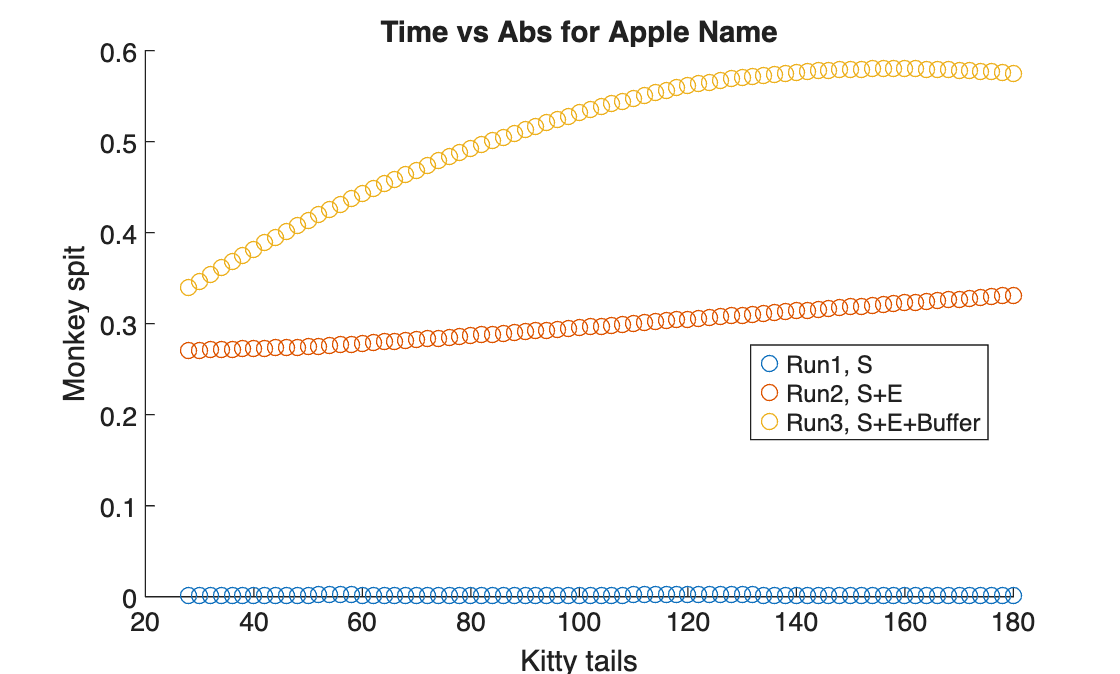

% Extract the data columns from the table and store them as arrays
% time should be the same for all data files, so only import the first
time = Run1.Time;
Run1_Abs= Run1.Absorbance;
Run2_Abs= Run2.Absorbance; 
Run3_Abs = Run3.Absorbance;

% plot the data to check correct import
% remove data points as necessary
figure 
hold on
plot(time, Run1_Abs, 'o')
plot(time, Run2_Abs, 'o')
plot(time, Run3_Abs, 'o')
title('Time vs Abs for Apple Name')
xlabel('Kitty tails')
ylabel('Monkey spit')
legend('Run1, S', 'Run2, S+E', 'Run3, S+E+Buffer', 'Location', 'best')
hold off


% be sure to change the title and labels approriately if you use this in
% your lab notebook

### Calculate Initial Velocity (rate)

The velocity at any time is the derivitives of the Absorbance with respect to time. We can use the diff() function to calcuate the derrivatives. The derivative vectors will have one fewer element than the time array, so create a new time array to compensate. 

The y-intercept (at time zero) is the initial velocity (rate) of the reaction.

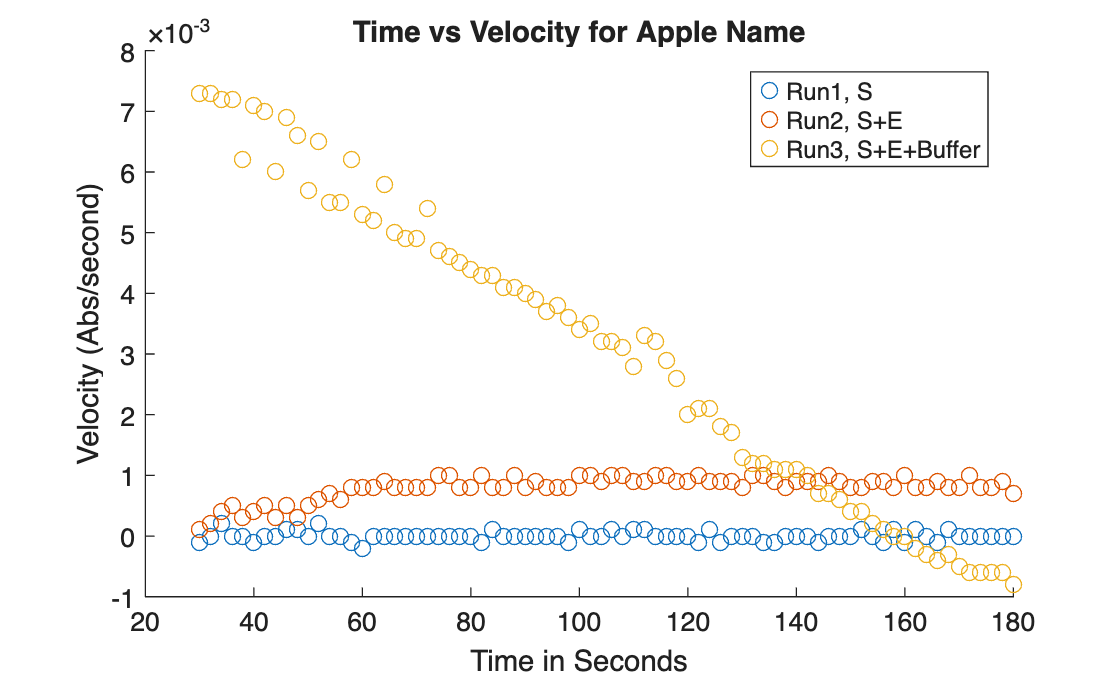

%take the differentials
Run1_V = diff(Run1_Abs);
Run2_V = diff(Run2_Abs);
Run3_V = diff(Run3_Abs);

time2 = time(2:end);

% plot the data
figure
hold on
plot(time2, Run1_V, 'o')
plot(time2, Run2_V, 'o')
plot(time2, Run3_V, 'o')
title('Time vs Velocity for Apple Name')
xlabel('Time in Seconds')
ylabel('Velocity (Abs/second)')
legend('Run1, S', 'Run2, S+E', 'Run3, S+E+Buffer', 'Location', 'best')
hold off

Use the fitlm function to fit a straight line to the data. The intercept is the initial velocity.

%Fit using fitlm
Run1_fit = fitlm(time2,Run1_V,"linear");
Run1_yfit = Run1_fit.Coefficients.Estimate(2)*time2 + Run1_fit.Coefficients.Estimate(1);

Run2_fit = fitlm(time2,Run2_V,"linear");
Run2_yfit = Run2_fit.Coefficients.Estimate(2)*time2 + Run2_fit.Coefficients.Estimate(1);

Run3_fit = fitlm(time2,Run3_V,"linear");
Run3_yfit = Run3_fit.Coefficients.Estimate(2)*time2 + Run3_fit.Coefficients.Estimate(1);


% Fitlm stores the results in a coefficients table:
Run1_fit.Coefficients

ans = 2×4 table
                    Estimate          SE         tStat     pValue 
                   ___________    __________    _______    _______

    (Intercept)     1.1005e-05    2.0999e-05     0.5241    0.60178
    x1             -9.2282e-08    1.8453e-07    -0.5001    0.61849


Run2_fit.Coefficients

ans = 2×4 table
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)    0.00050029    4.9495e-05    10.108    1.3878e-15
    x1             2.8168e-06    4.3494e-07    6.4764    9.1517e-09


Run3_fit.Coefficients

ans = 2×4 table
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)      0.0089856    8.0462e-05     111.68    3.0518e-84
    x1             -5.6029e-05    7.0706e-07    -79.242    2.6234e-73



V0_Run1 = Run1_fit.Coefficients.Estimate(1);
V0_Run1_err = Run1_fit.Coefficients.SE(1);
V0_Run2 = Run2_fit.Coefficients.Estimate(1);
V0_Run2_err = Run2_fit.Coefficients.SE(1);
V0_Run3 = Run3_fit.Coefficients.Estimate(1);
V0_Run3_err = Run3_fit.Coefficients.SE(1);


fprintf('V0 Run1: %.2e ± %.2e\n', V0_Run1, V0_Run1_err);

V0 Run1: 1.10e-05 ± 2.10e-05


fprintf('V0 Run2: %.2e ± %.2e\n', V0_Run2, V0_Run2_err);

V0 Run2: 5.00e-04 ± 4.95e-05


fprintf('V0 Run3: %.2e ± %.2e\n', V0_Run3, V0_Run3_err);

V0 Run3: 8.99e-03 ± 8.05e-05


### Plot the fitted velocity vs time data

Check the data and the plot features. Adjust as necessary.

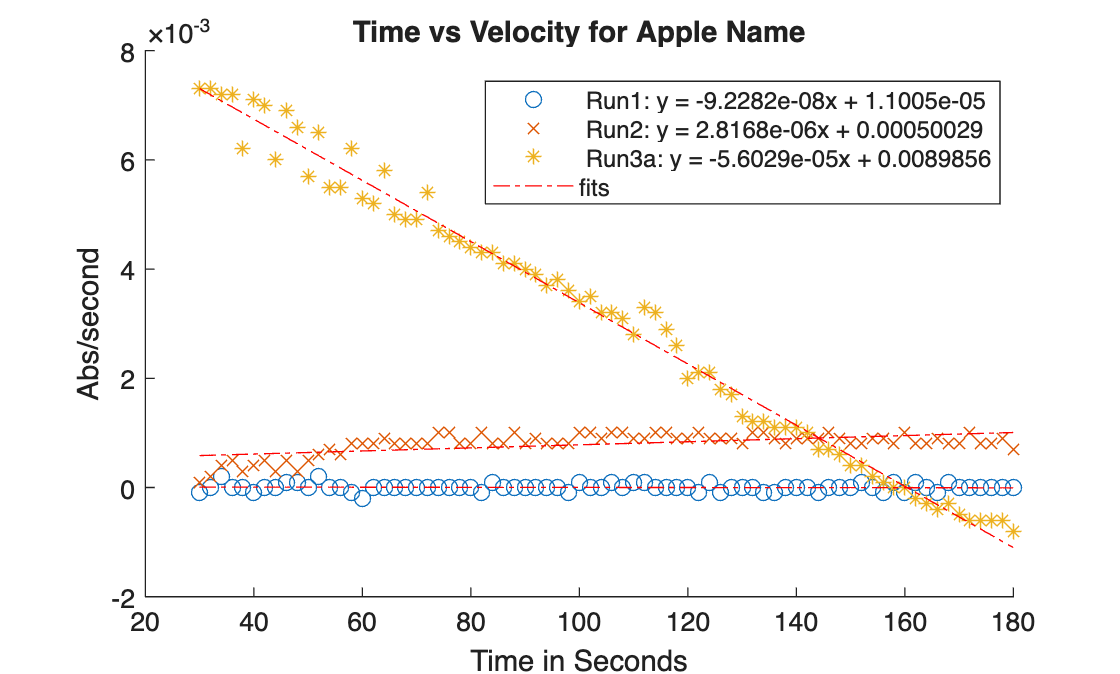

figure   %%Plot abs in one figure, plotting lines
hold on

plot(time2, Run1_V, 'o')
plot(time2, Run2_V, 'x')
plot(time2, Run3_V, '*')
title('Time vs Velocity for Apple Name')
xlabel('Time in Seconds')
ylabel('Abs/second')

plot(time2,Run1_yfit,'r-.');
eqn1 = string(" Run1: y = " + Run1_fit.Coefficients.Estimate(2)) + "x + " + Run1_fit.Coefficients.Estimate(1);

plot(time2,Run2_yfit,'r-.');
eqn2 = string(" Run2: y = " + Run2_fit.Coefficients.Estimate(2)) + "x + " + Run2_fit.Coefficients.Estimate(1);

plot(time2,Run3_yfit,'r-.');
eqn3 = string(" Run3a: y = " + Run3_fit.Coefficients.Estimate(2)) + "x + " + Run3_fit.Coefficients.Estimate(1);


legend(eqn1, eqn2, eqn3,'fits','Location', 'best')

hold off

# Part IB: What variety of apple would you choose for a fruit salad?

If your goal was to create a fruit salad that had fresh-looking apples, what variety of apples would be best? 

To answer this question, all the students in this course will divide up into teams. Each team will choose a different variety of apple to study, and the whole class will share data using a shared spreadsheet. 

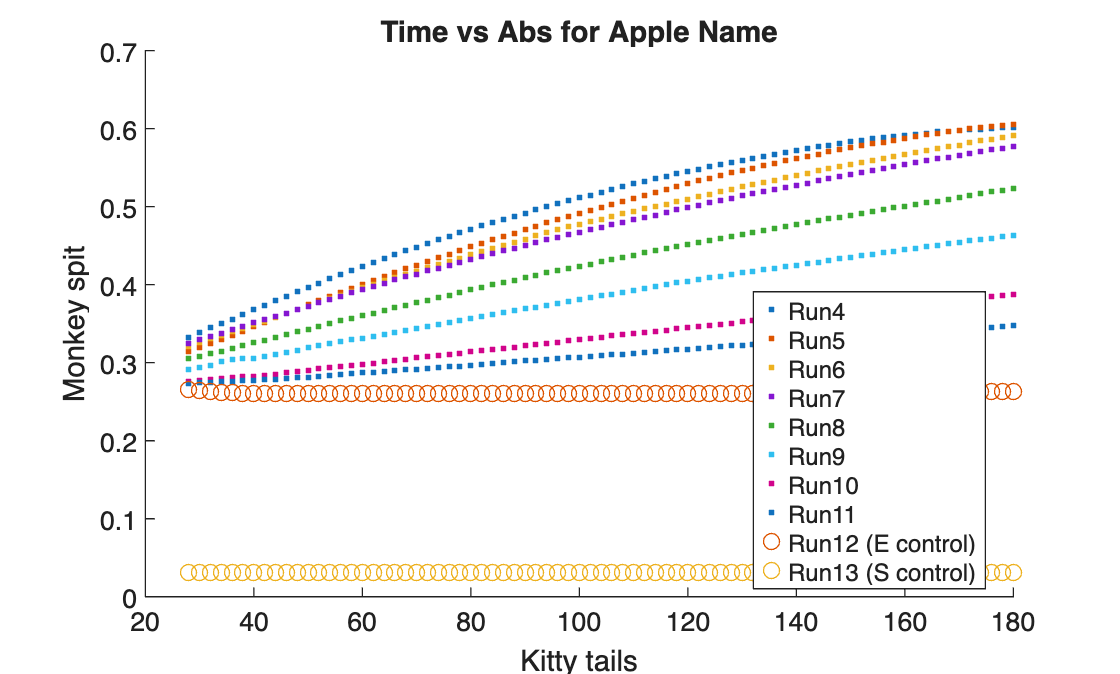

% Extract the data columns from the table and store them as arrays
% time should be the same for all data files, so only import the first

time = Run4.Time;
Run4_Abs= Run4.Absorbance;
Run5_Abs= Run5.Absorbance; 
Run6_Abs = Run6.Absorbance;
Run7_Abs = Run7.Absorbance;
Run8_Abs = Run8.Absorbance;
Run9_Abs = Run9.Absorbance;
Run10_Abs = Run10.Absorbance;
Run11_Abs = Run11.Absorbance;
Run12_Abs = Run12.Absorbance;
Run13_Abs = Run13.Absorbance;

% plot the data to check correct import
% remove data points as necessary
figure 
hold on
plot(time, Run4_Abs, '.')
plot(time, Run5_Abs, '.')
plot(time, Run6_Abs, '.')
plot(time, Run7_Abs, '.')
plot(time, Run8_Abs, '.')
plot(time, Run9_Abs, '.')
plot(time, Run10_Abs, '.')
plot(time, Run11_Abs, '.')
plot(time, Run12_Abs, 'o')
plot(time, Run13_Abs, 'o')
title('Time vs Abs for Apple Name')
xlabel('Kitty tails')
ylabel('Monkey spit')
legend('Run4', 'Run5', 'Run6', 'Run7', 'Run8', 'Run9', 'Run10', 'Run11', 'Run12 (E control)', 'Run13 (S control)', 'Location', 'best')
hold off



% be sure to change the title and labels approriately if you use this in
% your lab notebook

## Velocity (rate)

The velocity at any time is the derivitives of the Absorbance with respect to time. We can use the diff() function to calcuate the derrivatives. The derivative vectors will have one fewer element than the time array, so create a new time array to compensate. 

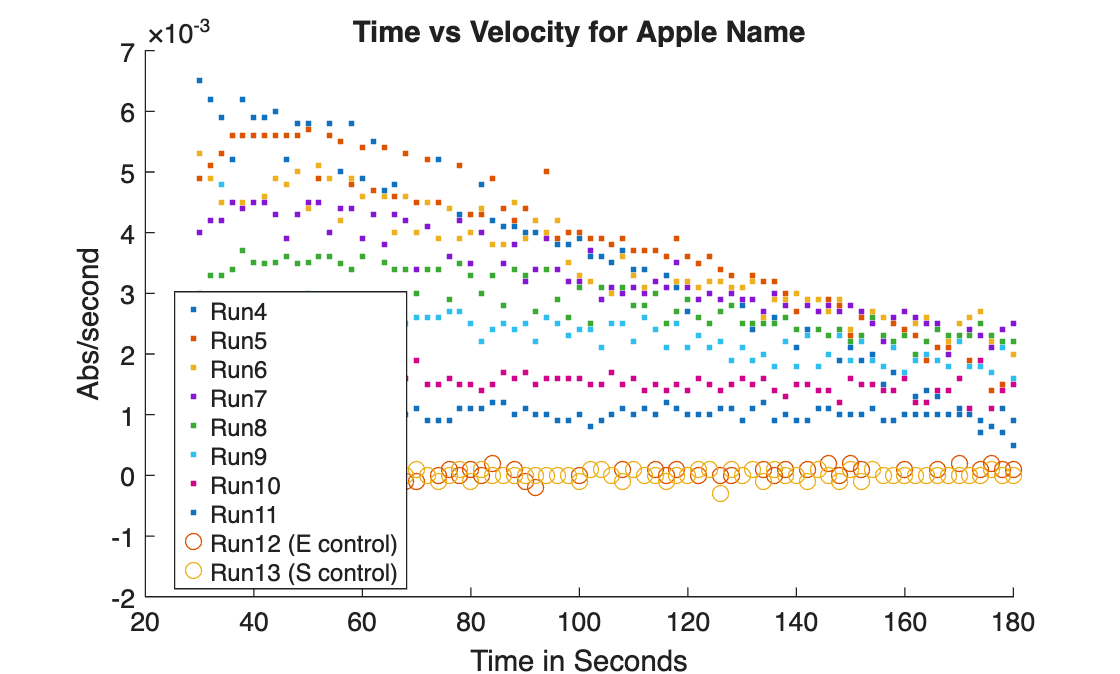

%take the differentials
Run4_V = diff(Run4_Abs);
Run5_V = diff(Run5_Abs);
Run6_V = diff(Run6_Abs);
Run7_V = diff(Run7_Abs);
Run8_V = diff(Run8_Abs);
Run9_V = diff(Run9_Abs);
Run10_V = diff(Run10_Abs);
Run11_V = diff(Run11_Abs);
Run12_V = diff(Run12_Abs);
Run13_V = diff(Run13_Abs);
time2 = time(2:end);

%plot the data
figure
hold on
plot(time2, Run4_V, '.')
plot(time2, Run5_V, '.')
plot(time2, Run6_V, '.')
plot(time2, Run7_V, '.')
plot(time2, Run8_V, '.')
plot(time2, Run9_V, '.')
plot(time2, Run10_V, '.')
plot(time2, Run11_V, '.')
plot(time2, Run12_V, 'o')
plot(time2, Run13_V, 'o')
title('Time vs Velocity for Apple Name')
xlabel('Time in Seconds')
ylabel('Abs/second')
legend('Run4', 'Run5', 'Run6', 'Run7', 'Run8', 'Run9', 'Run10', 'Run11', 'Run12 (E control)', 'Run13 (S control)', 'Location', 'best')
hold off

### Linear fitting of Velocity vs Time for each run 

Use the fitlm function to fit a straight line to the data. 

% Fit Time vs Velocity data using fitlm
Run4_fit = fitlm(time2,Run4_V,"linear");
Run4_yfit = Run4_fit.Coefficients.Estimate(2)*time2 + Run4_fit.Coefficients.Estimate(1);

Run5_fit = fitlm(time2,Run5_V,"linear");
Run5_yfit = Run5_fit.Coefficients.Estimate(2)*time2 + Run5_fit.Coefficients.Estimate(1);

Run6_fit = fitlm(time2,Run6_V,"linear");
Run6_yfit = Run6_fit.Coefficients.Estimate(2)*time2 + Run6_fit.Coefficients.Estimate(1);

Run7_fit = fitlm(time2,Run7_V,"linear");
Run7_yfit = Run7_fit.Coefficients.Estimate(2)*time2 + Run7_fit.Coefficients.Estimate(1);

Run8_fit = fitlm(time2,Run8_V,"linear");
Run8_yfit = Run8_fit.Coefficients.Estimate(2)*time2 + Run8_fit.Coefficients.Estimate(1);

Run9_fit = fitlm(time2,Run9_V,"linear");
Run9_yfit = Run9_fit.Coefficients.Estimate(2)*time2 + Run9_fit.Coefficients.Estimate(1);

Run10_fit = fitlm(time2,Run10_V,"linear");
Run10_yfit = Run10_fit.Coefficients.Estimate(2)*time2 + Run10_fit.Coefficients.Estimate(1);

Run11_fit = fitlm(time2,Run11_V,"linear");
Run11_yfit = Run11_fit.Coefficients.Estimate(2)*time2 + Run11_fit.Coefficients.Estimate(1);

Run12_fit = fitlm(time2,Run12_V,"linear");
Run12_yfit = Run12_fit.Coefficients.Estimate(2)*time2 + Run12_fit.Coefficients.Estimate(1);

Run13_fit = fitlm(time2,Run13_V,"linear");
Run13_yfit = Run13_fit.Coefficients.Estimate(2)*time2 + Run13_fit.Coefficients.Estimate(1);


% Fitlm stores the results in a coefficients table:
Run4_fit.Coefficients

ans = 2×4 table
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)       0.007367    7.3932e-05     99.646    1.3295e-80
    x1             -3.6377e-05    6.4967e-07    -55.993    2.4859e-62


Run5_fit.Coefficients

ans = 2×4 table
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)      0.0067201    8.8634e-05     75.819    6.6196e-72
    x1             -2.7422e-05    7.7887e-07    -35.208    5.7068e-48


Run6_fit.Coefficients

ans = 2×4 table
                    Estimate          SE        tStat       pValue  
                   ___________    __________    ______    __________

    (Intercept)      0.0055521    7.8509e-05     70.72    1.0679e-69
    x1             -1.8992e-05    6.8989e-07    -27.53    1.2732e-40


Run7_fit.Coefficients

ans = 2×4 table
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)      0.0049328    7.1517e-05     68.974    6.6058e-69
    x1             -1.5338e-05    6.2846e-07    -24.405    3.9494e-37


Run8_fit.Coefficients

ans = 2×4 table
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)       0.003916    6.3264e-05       61.9    1.7333e-65
    x1             -9.9522e-06    5.5593e-07    -17.902    1.3135e-28


Run9_fit.Coefficients

ans = 2×4 table
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)      0.0028323    0.00012546     22.576    6.4297e-35
    x1             -5.4204e-06    1.1025e-06    -4.9166    5.1528e-06


Run10_fit.Coefficients

ans = 2×4 table
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)      0.0015012    4.9453e-05      30.357    1.6435e-43
    x1             -2.2488e-07    4.3457e-07    -0.51747       0.60637


Run11_fit.Coefficients

ans = 2×4 table
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)    0.00085067    4.4457e-05    19.135    2.2571e-30
    x1              1.134e-06    3.9067e-07    2.9027     0.0048726


Run12_fit.Coefficients

ans = 2×4 table
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)    -0.00037775    7.6321e-05    -4.9495    4.5393e-06
    x1              3.2844e-06    6.7067e-07     4.8971     5.553e-06


Run13_fit.Coefficients

ans = 2×4 table
                    Estimate          SE          tStat      pValue 
                   ___________    __________    _________    _______

    (Intercept)    -7.1689e-07    1.9822e-05    -0.036166    0.97125
    x1               4.442e-08    1.7419e-07      0.25501    0.79942


% This extracts the initial velocity and standard error from the
% Coefficients table
%V0_Run4 = Run4_fit.Coefficients.Estimate(1); % initial velocity in Estimate column Coefficients table
V0_Run4_err = Run4_fit.Coefficients.SE(1); % standard error in the SE column of Coefficients table
%V0_Run5 = Run5_fit.Coefficients.Estimate(1);
V0_Run5_err = Run5_fit.Coefficients.SE(1);
%V0_Run6 = Run6_fit.Coefficients.Estimate(1);
V0_Run6_err = Run6_fit.Coefficients.SE(1);
%V0_Run7 = Run7_fit.Coefficients.Estimate(1);
V0_Run7_err = Run7_fit.Coefficients.SE(1);
%V0_Run8 = Run8_fit.Coefficients.Estimate(1);
V0_Run8_err = Run8_fit.Coefficients.SE(1);
%V0_Run9 = Run9_fit.Coefficients.Estimate(1);
V0_Run9_err = Run9_fit.Coefficients.SE(1);
%V0_Run10 = Run10_fit.Coefficients.Estimate(1);
V0_Run10_err = Run10_fit.Coefficients.SE(1);
%V0_Run11 = Run11_fit.Coefficients.Estimate(1);
V0_Run11_err = Run11_fit.Coefficients.SE(1);
%V0_Run12 = Run12_fit.Coefficients.Estimate(1);
V0_Run12_err = Run12_fit.Coefficients.SE(1);
%V0_Run13 = Run13_fit.Coefficients.Estimate(1);
V0_Run13_err = Run13_fit.Coefficients.SE(1);


%Extract the initial velocity from each linear fit
% and set as a new variable
V0_Run4_raw = Run4_fit.Coefficients.Estimate(1); % initial velocity in Estimate column Coefficients table
V0_Run5_raw = Run5_fit.Coefficients.Estimate(1);
V0_Run6_raw = Run6_fit.Coefficients.Estimate(1);
V0_Run7_raw = Run7_fit.Coefficients.Estimate(1);
V0_Run8_raw = Run8_fit.Coefficients.Estimate(1);
V0_Run9_raw = Run9_fit.Coefficients.Estimate(1);
V0_Run10_raw = Run10_fit.Coefficients.Estimate(1);
V0_Run11_raw = Run11_fit.Coefficients.Estimate(1);
V0_Run12_raw = Run12_fit.Coefficients.Estimate(1);
V0_Run13_raw = Run13_fit.Coefficients.Estimate(1);

% optional correction: only correct if you decide it is necessary
% to correct, remove % in all lines below

%controls = [V0_Run12 V0_Run13]
%baseline = mean(controls)
V0_Run4 = V0_Run4_raw % - baseline;

V0_Run4 = 0.0074

V0_Run5 = V0_Run5_raw % - baseline;

V0_Run5 = 0.0067

V0_Run6 = V0_Run6_raw % - baseline;

V0_Run6 = 0.0056

V0_Run7 = V0_Run7_raw % - baseline;

V0_Run7 = 0.0049

V0_Run8 = V0_Run8_raw % - baseline;

V0_Run8 = 0.0039

V0_Run9 = V0_Run9_raw % - baseline;

V0_Run9 = 0.0028

V0_Run10 = V0_Run10_raw % - baseline;

V0_Run10 = 0.0015

V0_Run11 = V0_Run11_raw % - baseline;

V0_Run11 = 8.5067e-04

V0_Run12 = V0_Run12_raw % - baseline;

V0_Run12 = -3.7775e-04

V0_Run13 = V0_Run13_raw % - baseline;

V0_Run13 = -7.1689e-07

%s Display results
fprintf('V0 Run4: %.2e ± %.2e\n', V0_Run4, V0_Run4_err);

V0 Run4: 7.37e-03 ± 7.39e-05


fprintf('V0 Run5: %.2e ± %.2e\n', V0_Run5, V0_Run5_err);

V0 Run5: 6.72e-03 ± 8.86e-05


fprintf('V0 Run6: %.2e ± %.2e\n', V0_Run6, V0_Run6_err);

V0 Run6: 5.55e-03 ± 7.85e-05


fprintf('V0 Run7: %.2e ± %.2e\n', V0_Run7, V0_Run7_err);

V0 Run7: 4.93e-03 ± 7.15e-05


fprintf('V0 Run8: %.2e ± %.2e\n', V0_Run8, V0_Run8_err);

V0 Run8: 3.92e-03 ± 6.33e-05


fprintf('V0 Run9: %.2e ± %.2e\n', V0_Run9, V0_Run9_err);

V0 Run9: 2.83e-03 ± 1.25e-04


fprintf('V0 Run10: %.2e ± %.2e\n', V0_Run10, V0_Run10_err);

V0 Run10: 1.50e-03 ± 4.95e-05


fprintf('V0 Run11: %.2e ± %.2e\n', V0_Run11, V0_Run11_err);

V0 Run11: 8.51e-04 ± 4.45e-05


fprintf('V0 Run12: %.2e ± %.2e\n', V0_Run12, V0_Run12_err);

V0 Run12: -3.78e-04 ± 7.63e-05


fprintf('V0 Run13: %.2e ± %.2e\n', V0_Run13, V0_Run13_err);

V0 Run13: -7.17e-07 ± 1.98e-05


## Plot Velocity vs Time for experiments with different $[S_0]$

Check the data and the plot features. Adjust as necessary.

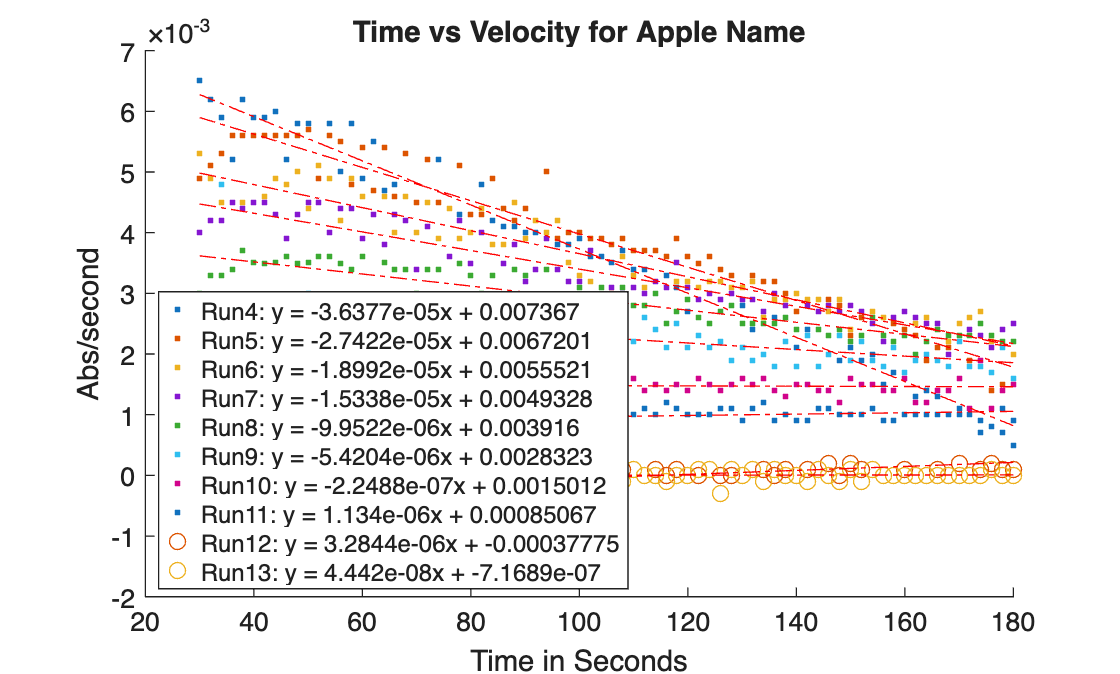

figure   %%Plot abs in one figure, plotting lines
hold on

plot(time2, Run4_V, '.')
plot(time2, Run5_V, '.')
plot(time2, Run6_V, '.')
plot(time2, Run7_V, '.')
plot(time2, Run8_V, '.')
plot(time2, Run9_V, '.')
plot(time2, Run10_V, '.')
plot(time2, Run11_V, '.')
plot(time2, Run12_V, 'o')
plot(time2, Run13_V, 'o')
title('Time vs Velocity for Apple Name')
xlabel('Time in Seconds')
ylabel('Abs/second')

plot(time2,Run4_yfit,'r-.');
eqn4 = string(" Run4: y = " + Run4_fit.Coefficients.Estimate(2)) + "x + " + Run4_fit.Coefficients.Estimate(1);

plot(time2,Run5_yfit,'r-.');
eqn5 = string(" Run5: y = " + Run5_fit.Coefficients.Estimate(2)) + "x + " + Run5_fit.Coefficients.Estimate(1);

plot(time2,Run6_yfit,'r-.');
eqn6 = string(" Run6: y = " + Run6_fit.Coefficients.Estimate(2)) + "x + " + Run6_fit.Coefficients.Estimate(1);

plot(time2,Run7_yfit,'r-.');
eqn7 = string(" Run7: y = " + Run7_fit.Coefficients.Estimate(2)) + "x + " + Run7_fit.Coefficients.Estimate(1);

plot(time2,Run8_yfit,'r-.');
eqn8 = string(" Run8: y = " + Run8_fit.Coefficients.Estimate(2)) + "x + " + Run8_fit.Coefficients.Estimate(1);

plot(time2,Run9_yfit,'r-.');
eqn9 = string(" Run9: y = " + Run9_fit.Coefficients.Estimate(2)) + "x + " + Run9_fit.Coefficients.Estimate(1);

plot(time2,Run10_yfit,'r-.');
eqn10 = string(" Run10: y = " + Run10_fit.Coefficients.Estimate(2)) + "x + " + Run10_fit.Coefficients.Estimate(1);

plot(time2,Run11_yfit,'r-.');
eqn11 = string(" Run11: y = " + Run11_fit.Coefficients.Estimate(2)) + "x + " + Run11_fit.Coefficients.Estimate(1);

plot(time2,Run12_yfit,'r-.');
eqn12 = string(" Run12: y = " + Run12_fit.Coefficients.Estimate(2)) + "x + " + Run12_fit.Coefficients.Estimate(1);

plot(time2,Run13_yfit,'r-.');
eqn13 = string(" Run13: y = " + Run13_fit.Coefficients.Estimate(2)) + "x + " + Run13_fit.Coefficients.Estimate(1);


legend(eqn4, eqn5, eqn6, eqn7, eqn8, eqn9, eqn10, eqn11, eqn12, eqn13, 'Location', 'best')
hold off

## Michaelis-Menten

The Michaelis-Menten equation is typically represented as $v=\frac{V_{\max } \cdot[S]}{K_m+[S]}$ where $v$ is the reaction rate, $V_{\max }$ is the maximum reaction rate, $[S]$ is the substrate concentration, and $K_m$ is the Michaelis constant. 

First, we need to calcuate the initial substrate concentrations in each of the runs. The code below does this with the proper user inputs. And, it generates a vector of the initial concentrations ($[S_o]$) and corresponding vector of initial rates ($V_o$).

%Enter concentrations and volumes
MW = 110.1; %molecular weight of substrate
stock_S_mgL = 588; % concentration (mg/L) of substrate stock solution
stock_S = stock_S_mgL/MW/1000; %in M

%enter volumes(V) of substrate in mL
TotV = 2.5; % total volume in cuvette (mL)
Vol4 = 2.000;     %volume of substrate added in run 4
Vol5 = 1.800;   %volume of substrate added in run 5
Vol6 = 1.600;
Vol7 = 1.400;
Vol8 = 1.200;
Vol9 = 1.000;
Vol10 = 0.800;
Vol11 = 0.600;
Vol12 = 0.400;
Vol13 = 0.200;

%Calcuate conc of Substrate in M
S4 = Vol4*stock_S/TotV;
S5 = Vol5*stock_S/TotV;
S6 = Vol6*stock_S/TotV;
S7 = Vol7*stock_S/TotV;
S8 = Vol8*stock_S/TotV;
S9 = Vol9*stock_S/TotV;
S10 = Vol10*stock_S/TotV;
S11 = Vol11*stock_S/TotV;
S12 = Vol12*stock_S/TotV;
S13 = Vol13*stock_S/TotV;

%define as vectors
S0 = [S4;S5;S6;S7;S8;S9;S10;S11;S12]; %initia substrate conc in M
V0 = [V0_Run4;
     V0_Run5;
     V0_Run6;
     V0_Run7;
     V0_Run8;
     V0_Run9;
     V0_Run10;
     V0_Run11;
     V0_Run12;]

V0 =     0.0074
    0.0067
    0.0056
    0.0049
    0.0039
    0.0028
    0.0015
    0.0009
   -0.0004


% disp(S0) %remove % sign if you want to display substrate conc. vector
% disp(V0)  %remove % sign if you want to display initial rate vector

**Save your workspace!**

Visualize the data in a plot

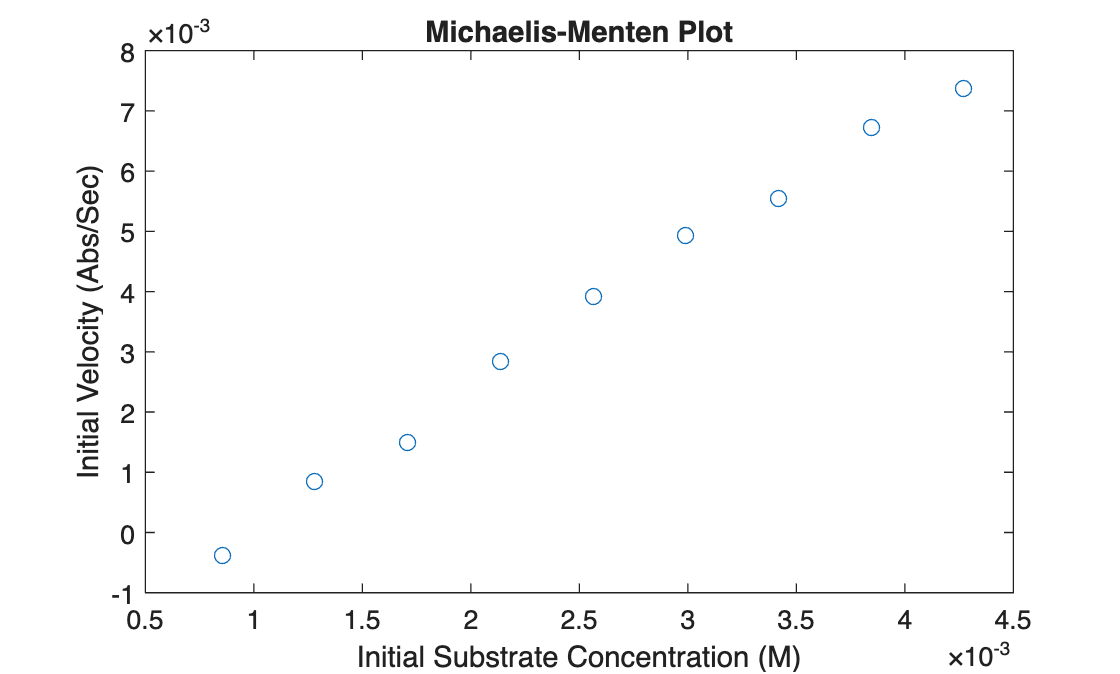

plot(S0,V0, 'o')
title('Michaelis-Menten Plot')
xlabel('Initial Substrate Concentration (M)')
ylabel('Initial Velocity (Abs/Sec)')

%We can use the max value of the V0 vector as an approximation of the Vmax
% This can help with fitting below
Vmax_guess = max(V0)

Vmax_guess = 0.0074

### Michaelis-Menton Least Squares Fitting

The code below was auto-generated using MatLab's Curve Fitter App and then customized for this script. 

*You will need the Curve Fitting Toolbox to proceed.*

**Fit the data**

%CREATEFIT(S0,V0)
%  Create a fit.
%
%  Data for 'Michaelis-Menton' fit:
%      X Input: S0
%      Y Output: V0
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 18-Feb-2024 10:30:32


%% Fit: 'Michaelis-Menton'.
[xDataMM, yDataMM] = prepareCurveData( S0, V0 );

% Set up fittype and options.
ftMM = fittype( 'Vmax*S0/(Km+S0)', 'independent', 'S0', 'dependent', 'Rate' );
optsMM = fitoptions( 'Method', 'NonlinearLeastSquares' );
optsMM.Display = 'Off';
optsMM.MaxIter = 1000;
optsMM.StartPoint = [0.005 0.006];

% Fit model to data.
[fitresult_MM, gof] = fit( xDataMM, yDataMM, ftMM, optsMM );

% Create a figure for the plots.
figure( 'Name', 'Michaelis-Menton' );
% Get the coefficients from the fit result
coefficients = coeffvalues(fitresult_MM);

% Get the confidence intervals for the coefficients
conf_intervals = confint(fitresult_MM);

% Combine coefficients and confidence intervals
coefficients_with_bounds = [coefficients; conf_intervals];

% Create a table with coefficients and bounds
coefficients_table = array2table(coefficients_with_bounds, 'VariableNames', {'Vmax', 'Km'}, 'RowNames', {'Coefficient', 'Lower Bound', 'Upper Bound'})

coefficients_table = 3×2 table
                    Vmax        Km   
                   _______    _______

    Coefficient     1.0765     1.6665
    Lower Bound    -251.49    -388.12
    Upper Bound     253.64     391.45



%Calcuate confidence interval
Vmax_conf = abs(coefficients_with_bounds(2)-coefficients_with_bounds(3))/2;
Kmax_conf = abs(coefficients_with_bounds(5)-coefficients_with_bounds(6))/2;
fprintf('Fitted Vmax: %.2e ± %.2e\n', fitresult_MM.Vmax, Vmax_conf);

Fitted Vmax: 1.67e+00 ± 2.53e+02


fprintf('Fitted Km: %.2e ± %.2e\n', fitresult_MM.Km, Kmax_conf);

Fitted Km: 1.08e+00 ± 3.90e+02


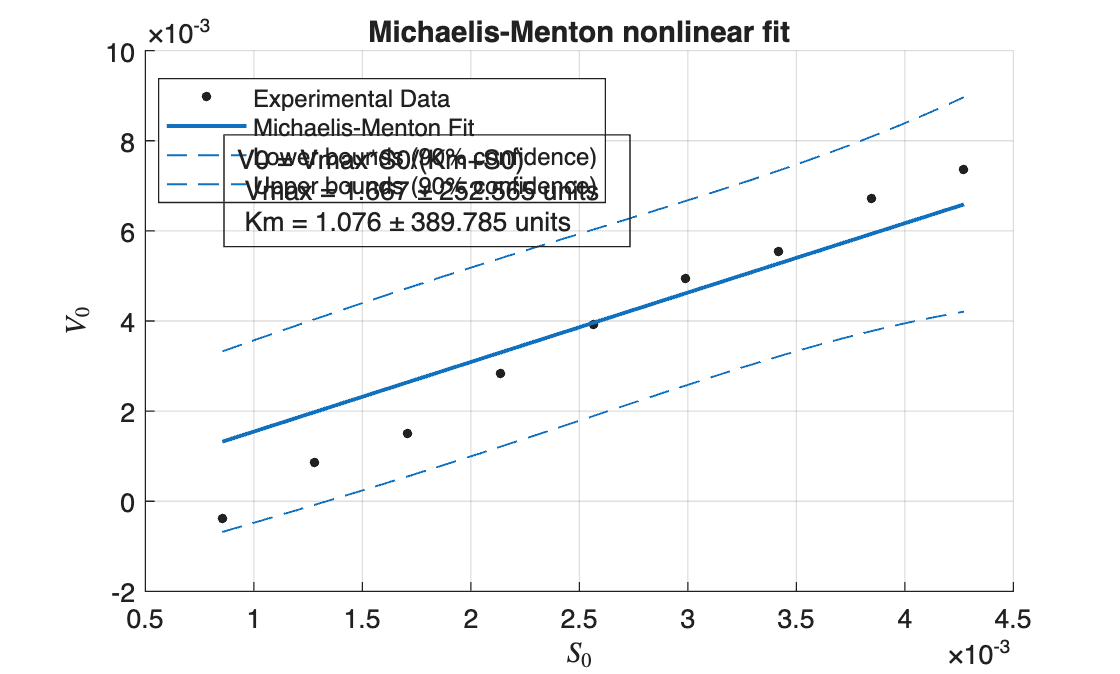

% Plot fit with data.
figure( 'Name', 'Michaelis Menton' );
hold on
MM = plot( fitresult_MM, xDataMM, yDataMM, 'predobs', 0.9 );
legend( MM, 'Experimental Data', 'Michaelis-Menton Fit', 'Lower bounds (90% confidence)', 'Upper bounds (90% confidence)', 'Location', 'best', 'Interpreter', 'none' );
xlabel( '$S_0$', 'Interpreter', 'latex' );
ylabel( '$V_0$', 'Interpreter', 'latex' );
title('Michaelis-Menton nonlinear fit')
% Add an annotation box
dim = [0.2 0.5 0.3 0.3];
eqn_MMVmax = string(" Vmax = " + sprintf('%.3f', fitresult_MM.Vmax) + " ± " + sprintf('%.3f', Vmax_conf) + " units");
eqn_MMKm = string(" Km = " + sprintf('%.3f', fitresult_MM.Km) + " ± " + sprintf('%.3f', Kmax_conf) + " units");

str = {'V0 = Vmax*S0/(Km+S0)', eqn_MMVmax, eqn_MMKm };
annotation('textbox',dim,'String',str,'FitBoxToText','on');
grid on

hold off

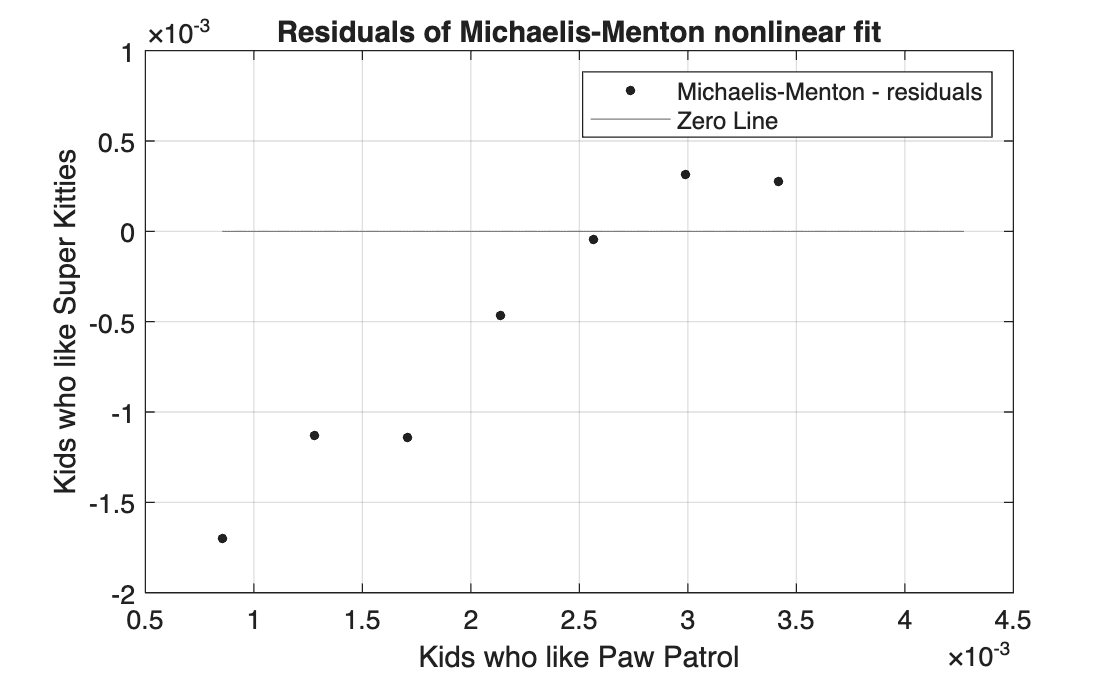

% Plot residuals.
figure( 'Name', 'Michaelis-Menton Residuals' );
MM_r = plot( fitresult_MM, xDataMM, yDataMM, 'residuals' );
legend( MM_r ,'Michaelis-Menton - residuals', 'Zero Line', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Kids who like Paw Patrol' );
ylabel( 'Kids who like Super Kitties' );
title('Residuals of Michaelis-Menton nonlinear fit')
grid on

## Lineweaver -Burke

The Lineweaer-Burke plot is a linearization of the Michaelis-Menton equation. In an era before computers could do non-linear fitting, most scientists used this method to determine Km and Vmax. However, it is highly criticized because its use applies the wrong statistical model to interpret the data. Though its use to derive constants is not advised, it is useful for visualizing the effect of substrate or inhibitor concentration on kinetic rate data (especially for part II).

**Prepare the data:**

In the vectors below, you may need to delete data from the highest concetrations of substrate because they may lie outside of the linear portion of the L-B plot. The code to do this is below, and you may need to remove some of the % signs to remove more data points.

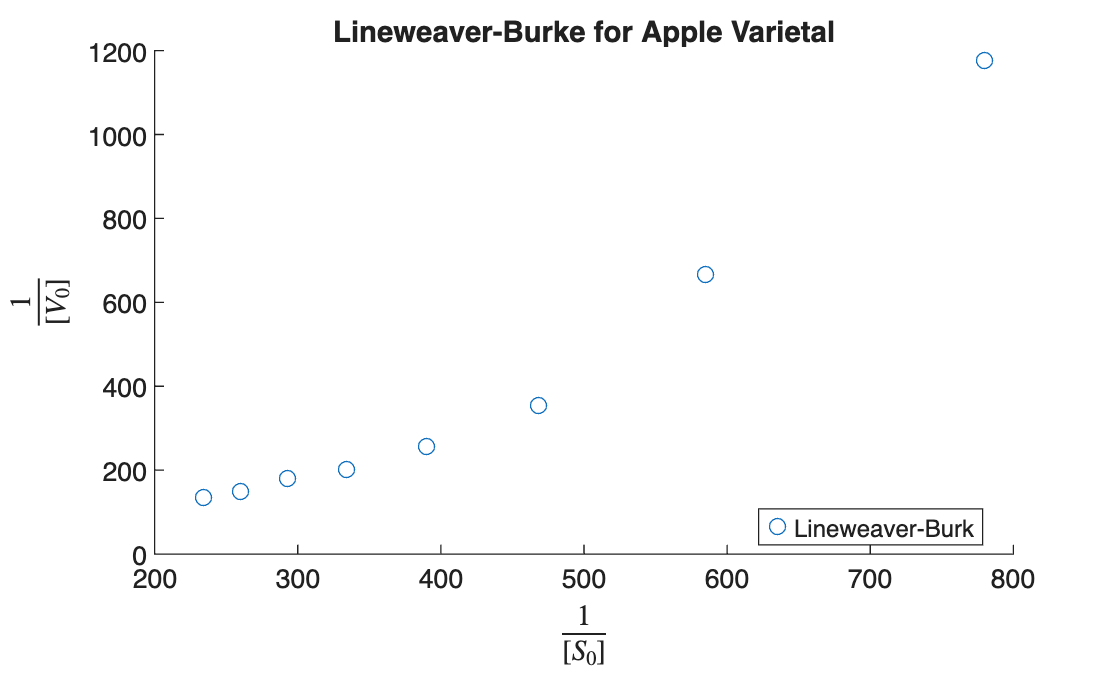

inverse_S0 = 1 ./ S0; 
inverse_V0 = 1 ./ V0; 

% delete 1/0 = infinity
inverse_S0(9)=[];  %inverse_S0(8)=[];  %inverse_S0(7)=[];

% adjust this array to match inverse_S0
inverse_V0(9)=[];  %inverse_V0(8)=[];   %inverse_V0(7)=[]

%plot the result and visually check for approximate linearity
figure( 'Name', 'Lineweaver-Burke Initial' );
hold on
plot(inverse_S0, inverse_V0, 'o')
title('Lineweaver-Burke for Apple Varietal')
xlabel('$\frac{1}{[S_0]}$', 'Interpreter', 'latex')
ylabel('$\frac{1}{[V_0]}$', 'Interpreter', 'latex')
legend('Lineweaver-Burk', 'Location', 'best')
hold off


%add annotation to create a 'final' plot!

**Fit the data linearized data.**

This code was automatically generated by MatLab's Curve fitting App and modified for this script.

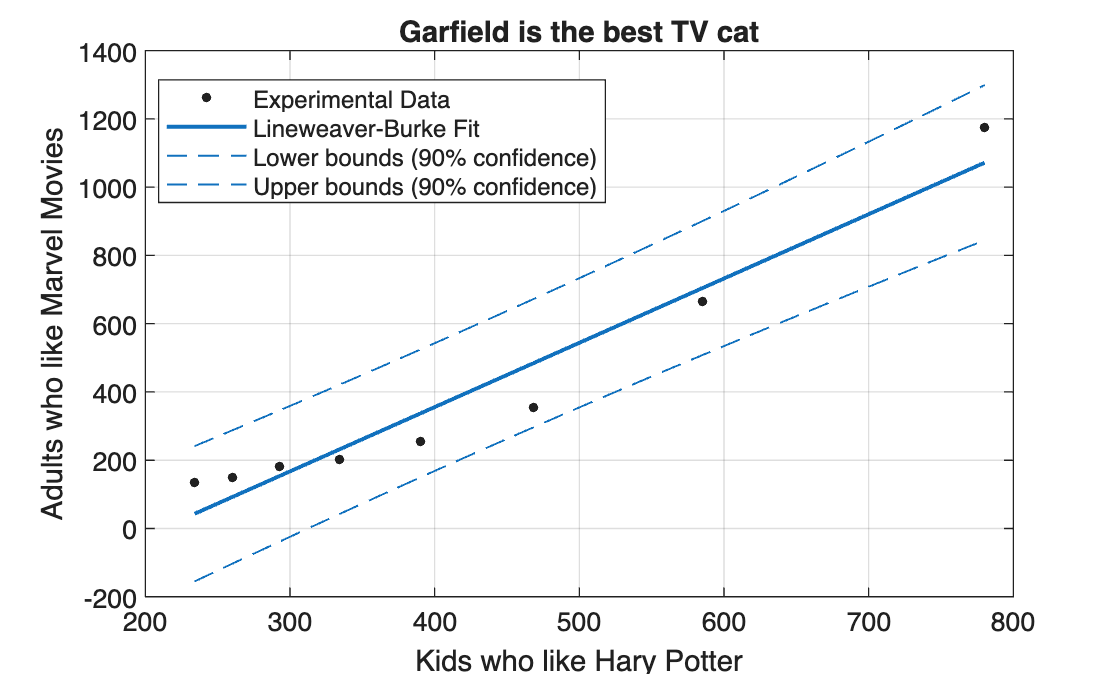

%CREATEFIT(INVERSE_S0,INVERSE_V0)
%  Create a fit.
%
%  Data for 'Lineweaver-Burke' fit:
%      X Input: inverse_S0
%      Y Output: inverse_V0
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 18-Feb-2024 10:24:10


%% Fit: 'Lineweaver-Burke'.
[xDataLB, yDataLB] = prepareCurveData( inverse_S0, inverse_V0 );

% Set up fittype and options.
ftLB = fittype( 'poly1' );

% Fit model to data.
[fitresultLB, gof] = fit( xDataLB, yDataLB, ftLB );

% Plot the result
figure( 'Name', 'Lineweaver-Burke' );
LB = plot( fitresultLB, xDataLB, yDataLB, 'predobs', 0.9 );
legend( LB, 'Experimental Data', 'Lineweaver-Burke Fit', 'Lower bounds (90% confidence)', 'Upper bounds (90% confidence)', 'Location', 'best', 'Interpreter', 'none' );
xlabel( 'Kids who like Hary Potter' );
ylabel( 'Adults who like Marvel Movies' );
title('Garfield is the best TV cat')

% use the code blocks above as examples of how you can add an anotation or
% text to the plot. Or, use the GUI to create a "final plot"
grid on

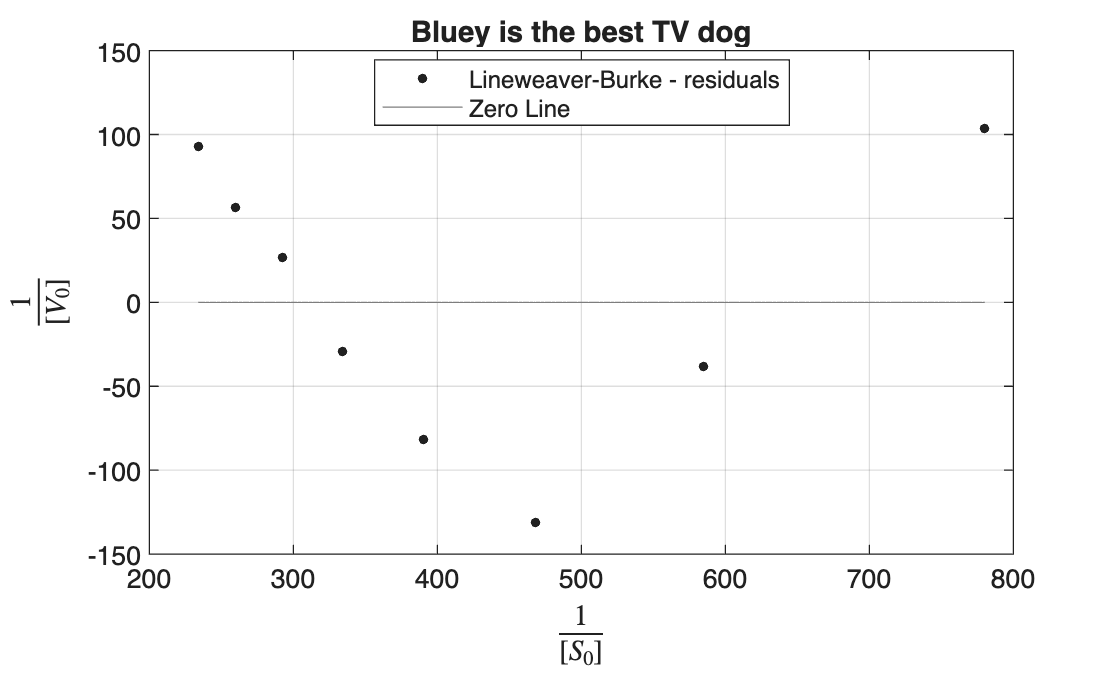

% Plot residuals.
figure( 'Name', 'Lineweaver-Burke Residuals' );
LB_r = plot( fitresultLB, xDataLB, yDataLB, 'residuals' );
legend( LB_r, 'Lineweaver-Burke - residuals', 'Zero Line', 'Location', 'best', 'Interpreter', 'none' );
% Label axes
xlabel( '$\frac{1}{[S_0]}$', 'Interpreter', 'latex' );
ylabel( '$\frac{1}{[V_0]}$', 'Interpreter', 'latex' );
title('Bluey is the best TV dog')
grid on

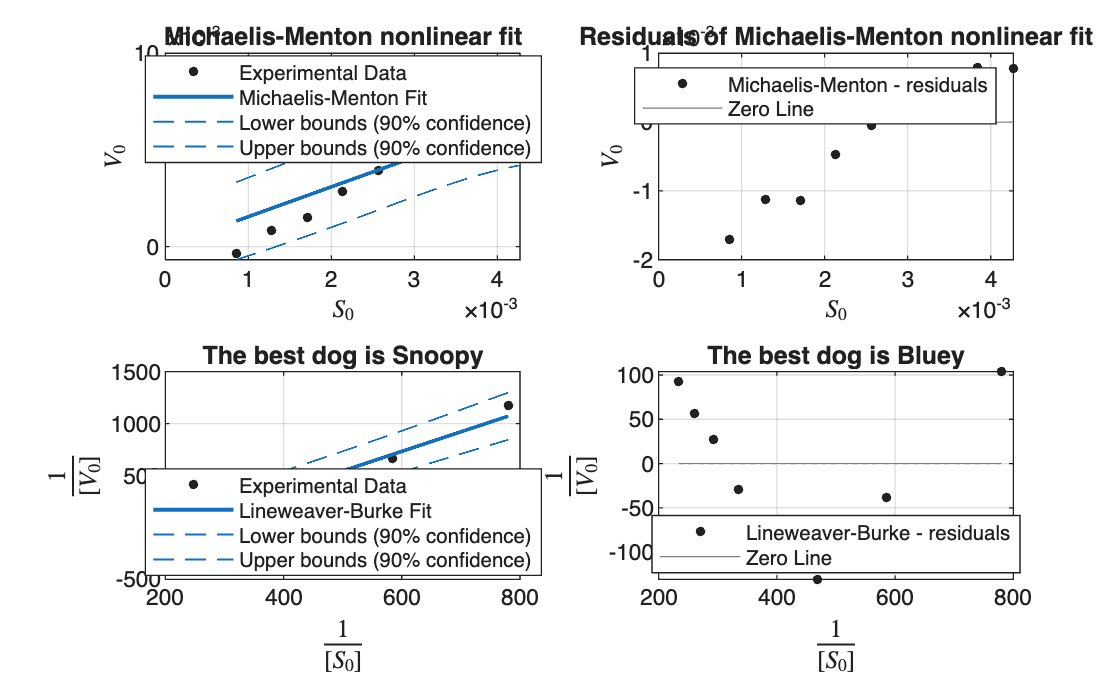

%Summary
% Create a figure for the plots.
figure( 'Name', 'Summary' );

% Plot MM.
subplot( 2, 2, 1 );
MM = plot( fitresult_MM, xDataMM, yDataMM, 'predobs', 0.9 );
legend( MM, 'Experimental Data', 'Michaelis-Menton Fit', 'Lower bounds (90% confidence)', 'Upper bounds (90% confidence)', 'Location', 'best', 'Interpreter', 'none' );
xlabel( '$S_0$', 'Interpreter', 'latex' );
ylabel( '$V_0$', 'Interpreter', 'latex' );
title('Michaelis-Menton nonlinear fit')
grid on

% Plot MM residuals.
subplot( 2, 2, 2 );
MM_r = plot( fitresult_MM, xDataMM, yDataMM, 'residuals' );
legend( MM_r ,'Michaelis-Menton - residuals', 'Zero Line', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( '$S_0$', 'Interpreter', 'latex' );
ylabel( '$V_0$', 'Interpreter', 'latex' );
title('Residuals of Michaelis-Menton nonlinear fit')
grid on

% Plot LB.
subplot( 2, 2, 3 );
LB = plot( fitresultLB, xDataLB, yDataLB, 'predobs', 0.9 );
legend( LB, 'Experimental Data', 'Lineweaver-Burke Fit', 'Lower bounds (90% confidence)', 'Upper bounds (90% confidence)', 'Location', 'best', 'Interpreter', 'none' );
xlabel( '$\frac{1}{[S_0]}$', 'Interpreter', 'latex' );
ylabel( '$\frac{1}{[V_0]}$', 'Interpreter', 'latex' );
title('The best dog is Snoopy')
grid on

% Plot residuals.
subplot( 2, 2, 4 );
LB_r = plot( fitresultLB, xDataLB, yDataLB, 'residuals' );
legend( LB_r, 'Lineweaver-Burke - residuals', 'Zero Line', 'Location', 'best', 'Interpreter', 'none' );
% Label axes
xlabel( '$\frac{1}{[S_0]}$', 'Interpreter', 'latex');
ylabel( '$\frac{1}{[V_0]}$', 'Interpreter', 'latex' );
title('The best dog is Bluey')
grid on

## Convert Lineweaver-Burke result to Michaelis-Menton Plot

% Generate data points for linear LB fit
inverseS0all = 1 ./ S0

inverseS0all = 1.0e+03 *

    0.2341
    0.2601
    0.2926
    0.3344
    0.3901
    0.4681
    0.5851
    0.7802
    1.1703


LB_fit = fitlm(inverse_S0,inverse_V0,"linear")

LB_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -397.78      83.249    -4.7782     0.0030684
    x1              1.8836     0.18374     10.251    5.0274e-05


Number of observations: 8, Error degrees of freedom: 6
Root Mean Squared Error: 90.7
R-squared: 0.946,  Adjusted R-Squared: 0.937
F-statistic vs. constant model: 105, p-value = 5.03e-05

LB_yfit = LB_fit.Coefficients.Estimate(2)*inverseS0all + LB_fit.Coefficients.Estimate(1)

LB_yfit = 1.0e+03 *

    0.0431
    0.0921
    0.1533
    0.2320
    0.3370
    0.4839
    0.7044
    1.0717
    1.8065



% Take inverse of LB fitted points
LB_V0 = 1 ./ LB_yfit

LB_V0 =     0.0232
    0.0109
    0.0065
    0.0043
    0.0030
    0.0021
    0.0014
    0.0009
    0.0006


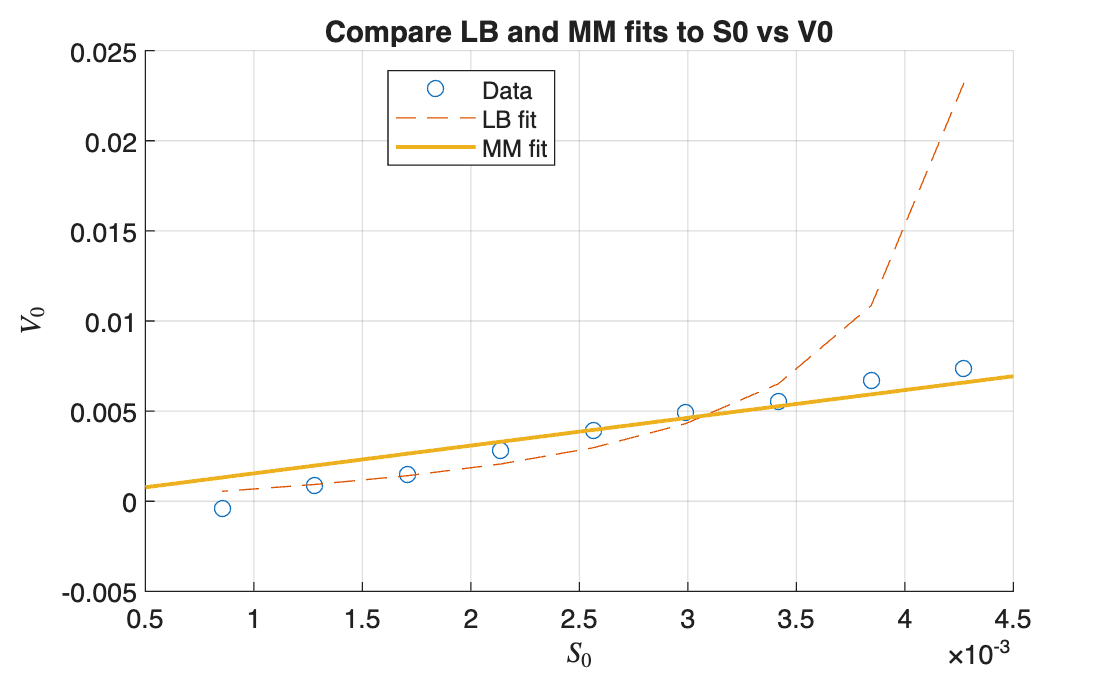

% Plot MM vs LB fits with S0 vs V0 data.
figure
hold on
plot(S0, V0, 'o')
plot(S0, LB_V0, '--')
plot(fitresult_MM)
legend( 'Data', 'LB fit', 'MM fit', 'Location', 'best', 'Interpreter', 'none' );
xlabel( '$S_0$', 'Interpreter', 'latex' );
ylabel( '$V_0$', 'Interpreter', 'latex' );
title('Compare LB and MM fits to S0 vs V0')
grid on
hold off

%ylim([0 0.005])  %This can control your axes


**Create a residuals plot!**

**Save your workspace!**